# Classify Image Using GoogLeNet

Copyright@ *Nabajeet Barman (nabajeetbarman4@gmail.com)*

This example shows how to classify an image using the pretrained deep convolutional neural network GoogLeNet. 

GoogleNet Paper: [https://arxiv.org/pdf/1409.4842.pdf](https://arxiv.org/pdf/1409.4842.pdf)

## Introduction 

The winner of the ILSVRC 2014 competition was **GoogleNet** from Google. It achieved a top-5 error rate of 6.67%! This was very close to human level performance which the organisers of the challenge were now forced to evaluate. As it turns out, this was actually rather hard to do and required some human training in order to beat GoogLeNets accuracy. GoogleNet has **22 layer**, and almost **12x less parameters** (So faster and less then Alexnet and much more accurate).

Their idea was to make a model that also could be **used on a smart-phone**

GoogLeNet has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input, and then outputs a label for the object in the image together with the probabilities for each of the object categories. 

There is another network available which was trained on Places365 is similar to the network trained on ImageNet, but classifies images into 365 different place categories, such as field, park, runway, and lobby. These networks have learned different feature representations for a wide range of images. The pretrained networks both have an image input size of 224-by-224. 

## Load Pretrained Network

Load the pretrained GoogLeNet network. This step requires the Deep Learning Toolbox™ Model *for GoogLeNet Network* support package. If you do not have the required support packages installed, then the software provides a download link. 

For a list of all pre-trained networks, click [here](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html#mw_45a8c0b2-26fa-48e9-905a-a7ed7b87bfc8)

clear
close all
clc
net = googlenet;

The image that you want to classify must have the same size as the input size of the network. For GoogLeNet, the first element of the `Layers` property of the network is the image input layer. The network input size is the `InputSize` property of the image input layer.  

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


The final element of the `Layers` property is the classification output layer. The `ClassNames` property of this layer contains the names of the classes learned by the network. View 10 random class names out of the total of 1000.

classNames = net.Layers(end).ClassNames;
numClasses = numel(classNames);
disp(classNames(randperm(numClasses,10)))

    'swab'
    'pug'
    'space shuttle'
    'boxer'
    'consomme'
    'ram'
    'Boston bull'
    'malamute'
    'jigsaw puzzle'
    'caldron'



## Read and Resize Image

Read and show the image that you want to classify.

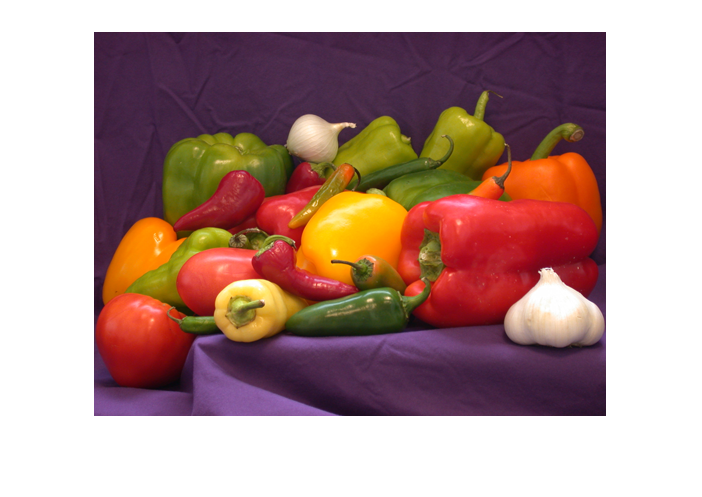

I = imread('peppers.png'); % file included with MATLAB
figure
imshow(I)

Display the size of the image. The image is 384-by-512 pixels and has three color channels (RGB).

size(I)

ans =    384   512     3


Resize the image to the input size of the network by using `imresize`. This resizing slightly changes the aspect ratio of the image.

I = imresize(I,inputSize(1:2)); % network input size is the InputSize 

B = imresize(A, SCALE) returns an image that is SCALE times the size of A, which is a grayscale, RGB, binary or a categorical image. If A has more than two dimensions, only the first two dimensions are resized.

`    imresize(A, SCALE, METHOD) `

`    imresize(A, [NUMROWS NUMCOLS], METHOD),`

`    imresize(X, MAP, SCALE, METHOD)`

`    imresize(X, MAP, [NUMROWS NUMCOLS], METHOD)`

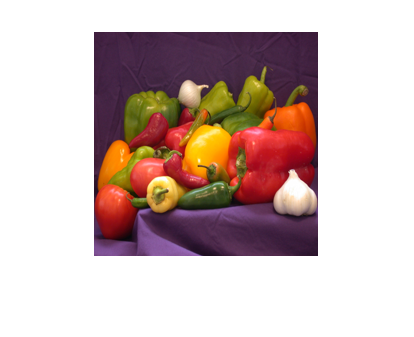

figure
imshow(I)

Depending on your application, you might want to resize the image in a different way. For example, you can crop the top left corner of the image by using `I(1:inputSize(1),1:inputSize(2),:)`. If you have Image Processing Toolbox™, then you can use the `imcrop` function.

## Classify Image

Classify the image and calculate the class probabilities using `classify`. The network correctly classifies the image as a bell pepper. A network for classification is trained to output a single label for each input image, even when the image contains multiple objects.

[label,scores] = classify(net,I);
label

label = categorical
     bell pepper 


Display the image with the predicted label and the predicted probability of the image having that label.

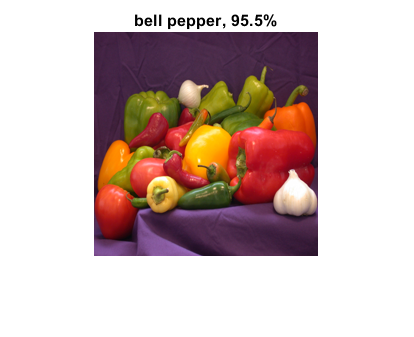

figure
imshow(I)
title(string(label) + ", " + num2str(100*scores(classNames == label),3) + "%");

% to check where in the classNames "bell pepper" class exists
Index = find(contains(classNames,'bell pepper'))

Index = 946

## **Display Top Predictions**

Display the top five predicted labels and their associated probabilities as a histogram. Because the network classifies images into so many object categories, and many categories are similar, it is common to consider the top-five accuracy when evaluating networks. The network classifies the image as a bell pepper with a high probability.

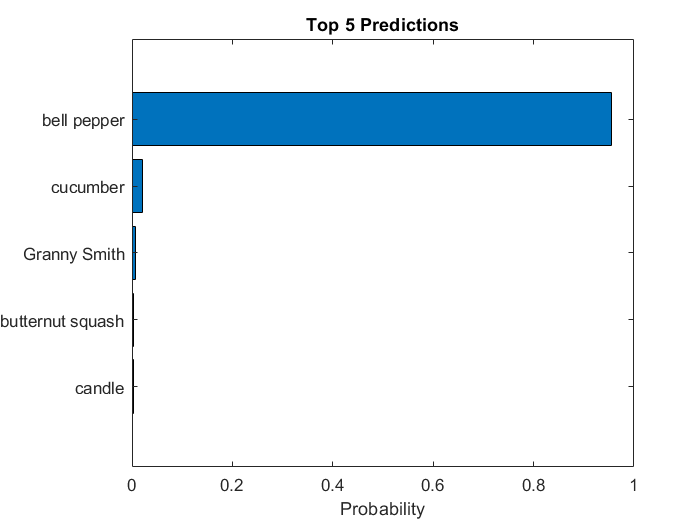

[~,idx] = sort(scores,'descend');
idx = idx(5:-1:1);
classNamesTop = net.Layers(end).ClassNames(idx);
scoresTop = scores(idx);

figure
barh(scoresTop)
xlim([0 1])
title('Top 5 Predictions')
xlabel('Probability')
yticklabels(classNamesTop)

# Workshop Task

Repeat the above steps for the following images and report your observations

- sherlock.jpg

- cameraman.tif

- strawberries.jpg

- baby.jpg